clc;
clear;
close all;

Ix = imread('INTENSIDADX.JPG');
Iy = imread('INTENSIDADY.JPG');
Id = imread('INTENSIDAD45ºDIAG.JPG');
Ia = imread('INTENSIDAD-45ºANTI.JPG');
Ir = imread('INTENSIDAD45ºRETARDADOR.JPG');
Il = imread('INTENSIDAD-45ºRETARDADOR.JPG');

S0_color = Ix + Iy;
S1_color = Ix - Iy;
S2_color = Id - Ia;
S3_color = Ir - Il;

S0_im = im2double(rgb2gray(S0_color));
S1_im = im2double(rgb2gray(S1_color));
S2_im = im2double(rgb2gray(S2_color));
S3_im = im2double(rgb2gray(S3_color));

S0 = mean(S0_im, 'all')

S0 = 0.5063

S1 = mean(S1_im, 'all')

S1 = 0.1101

S2 = mean(S2_im, 'all')

S2 = 0.1115

S3 = mean(S3_im, 'all')

S3 = 0.0166

% p global
p = sqrt(S1^2 + S2^2 + S3^2)/S0

p = 0.3112

% Elipse de polarización global
t = linspace(0, 2*pi, 128);
alpha = 0.5*atan(S2/S1)

alpha = 0.3958

Emax = sqrt(0.5*(S0 + sqrt(S1^2 + S2^2)))

Emax = 0.5757

Emin = sqrt(0.5*(S0 - sqrt(S1^2 + S2^2)))

Emin = 0.4181

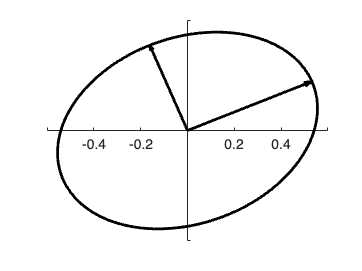

x = Emax*cos(t)*cos(alpha) - Emin*sin(t)*sin(alpha);
y = Emax*cos(t)*sin(alpha) + Emin*sin(t)*cos(alpha);

fig1 = figure;
hold on;
plot(x, y, 'k', 'LineWidth', 2);
quiver(0, 0, Emax*cos(alpha), Emax*sin(alpha), 'off', 'k', 'LineWidth', 2);
quiver(0, 0, -Emin*sin(alpha), Emin*cos(alpha), 'off', 'k', 'LineWidth', 2);
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
saveas(fig1, 'ElipsePolarizacionGlobal.png')
hold off;

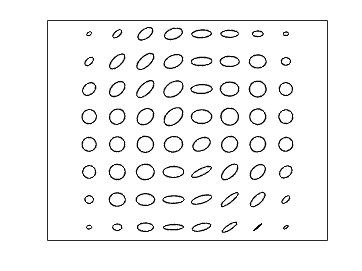

% Elipse de polarización local
%p_loc = zeros(8,8);
plt = figure;
for i=1:8
    for j=1:8
        S0 = mean(S0_im(340*i-339:340*i, 340*j-339:340*j), 'all');
        S1 = mean(S1_im(340*i-339:340*i, 340*j-339:340*j), 'all');
        S2 = mean(S2_im(340*i-339:340*i, 340*j-339:340*j), 'all');
        S3 = mean(S3_im(340*i-339:340*i, 340*j-339:340*j), 'all');
        % p_l = sqrt(S1^2 + S2^2 + S3^2)/S0;
        % p_loc(i, j) = p_l;

        t = linspace(0, 2*pi, 128);
        alpha = 0.5*atan(S2/S1);
        Emax = sqrt(0.5*(S0 + sqrt(S1^2 + S2^2)));
        Emin = sqrt(0.5*(S0 - sqrt(S1^2 + S2^2)));
        x = - 9 + 2*i + Emax*cos(t)*cos(alpha) - Emin*sin(t)*sin(alpha);
        y = 9 - 2*j + Emax*cos(t)*sin(alpha) + Emin*sin(t)*cos(alpha);
        plot(x, y, 'k', 'LineWidth', 1); hold on
    end
end
set(gca, 'XTick', [], 'YTick', []);
saveas(plt, 'ElipsePolarizacionLocal.png')
hold off;

% p local heatmap

% p_loc = zeros(20,20);
% for i=1:20
%     for j=1:20
%         S0 = mean(S0_im(136*i-135:136*i, 136*j-135:136*j), 'all');
%         S1 = mean(S1_im(136*i-135:136*i, 136*j-135:136*j), 'all');
%         S2 = mean(S2_im(136*i-135:136*i, 136*j-135:136*j), 'all');
%         S3 = mean(S3_im(136*i-135:136*i, 136*j-135:136*j), 'all');
%         p_l = sqrt(S1^2 + S2^2 + S3^2)/S0;
%         p_loc(i, j) = p_l;
%     end
% end

p_loc = sqrt(S1_im.^2 + S2_im.^2 + S3_im.^2)./S0_im;

fig = figure;
h = imshow(p_loc);
cb = colorbar;
cb.Label.String = 'Grado de p. local';
saveas(fig, 'HeatMapPolarización.png')